# [Solution] Applying an MPO onto an MPS

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): MPO representation of the AKLT Hamiltonian

The AKLT Hamiltonian has two interaction terms: the Heisenberg interaction and the biquadratic term (i.e., the squared Heisenberg interaction).

clear

[S,I] = getLocalSpace('Spin',1);

% bulk tensor of the MPO Hamiltonian
Hloc = cell((2+size(S,3)+size(S,3)^2)*[1 1]);
Hloc(:) = {zeros(size(I))};

`Hloc(1,1)` and `Hloc(end,end)` are for the identities.

Hloc{1,1} = I;
Hloc{end,end} = I;

`Hloc(end,2:4)` contain the spinor of the spin raising, $z$, and lowering operators, where the raising and lowering operators are divided by$\sqrt{2}$. And `Hloc(2:4,1)` are the Hermitian conjugates of `Hloc(end,2:4)`, respectively.

% Heisenberg interaction
for ito = (1:size(S,3)) % different components of spin operators
    Hloc{end,ito+1} = S(:,:,ito);
    Hloc{ito+1,1} = S(:,:,ito)';
end

`Hloc(end,5:13)` contain the direct product of two spinors of spin operators, multiplied with 1/3.

% % biquadratic term
for ito = (1:size(S,3)) 
    ids = size(S,3)*ito+1+(1:size(S,3));
    Hloc(end,ids) = {S(:,:,ito)/3};
    % 1/3 factor in the biquadratic term
    Hloc(ids,1) = {S(:,:,ito)'};
end
for ito = (1:size(S,3)) 
    ids = ((size(S,3)+ito+1):size(S,3):size(Hloc,1)-1);
    Hloc(end,ids) = cellfun(@(x) S(:,:,ito)*x, Hloc(end,ids), ...
        'UniformOutput', false);
    Hloc(ids,1) = cellfun(@(x) S(:,:,ito)'*x, Hloc(ids,1), ...
        'UniformOutput', false);
end

Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

Let's consider a short chain of length $L = 4$, where the Hamiltonian can be shown as a $3^4 \times 3^4$ matrix.

L = 4;

% MPO for the full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last index of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first index of the right leg

Hs_tot = 1; % initialize
for itN = (1:L)
    Hs_tot = contract(Hs_tot,2*itN,2*itN,Hs{itN},4,3);
end
% permute the left- and rightmost legs to the end
Hs_tot = permute(Hs_tot,[(2:2*L+2) 1]);

% merge the incoming legs into a thick incoming leg;
% merge the outgoing legs into a thick outgoing leg
Hs_tot = permute(Hs_tot,[(1:2:2*L) (2:2:2*L)]);
Hs_tot = reshape(Hs_tot,(size(I,1)^L)*[1 1]);
size(Hs_tot)

ans =     81    81


We compare `Hs_tot` with the AKLT Hamiltonian that is constructed iteratively by using the identity tensors without truncating or rotating them. To easily generate the biquadratic term depicted on the left side of the figure below, we obtain the squared spin operators as rank-3 by combining the third legs of the spin operators as in the middle and the right side of the figure.

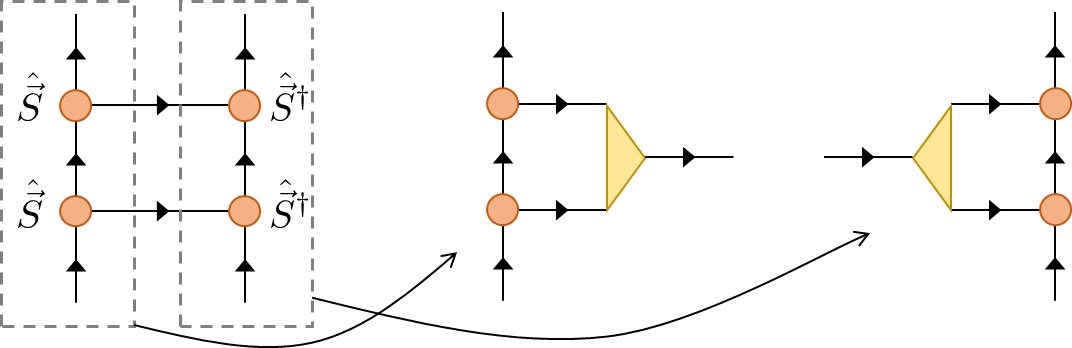

% diagram in the middle
S2 = contract(S,3,2,S,3,1);
A_S = getIdentity(S2,2,S2,4);
S2 = contract(S2,4,[2 4],A_S,3,[1 2]);
% diagram on the right
S3 = contract(conj(S),3,1,conj(S),3,2);
S3 = contract(S3,4,[2 4],conj(A_S),3,[1 2]);

Note that `S3` is not the Hermitian conjugate of `S2`.

Sdiff = S3 - permute(conj(S2),[2 1 3]);
max(abs(Sdiff(:)))

ans = 1

Initialize the Hamiltonian and the identity for the vacuum space corresponding to the leftmost dummy leg.

Hprev = 0; % initialize Hamiltonian
Aprev = 1; % identity for the vacuum

for itN = (1:L)
    % rank-3 identity tensor for the current iteration
    Anow = getIdentity(Aprev,2,I,2,[1 3 2]);

    % contract the Hamiltonian up to the last iteration with
    % ket and bra tensors
    Hnow = updateLeft(Hprev,2,Anow,[],[],Anow);

    if itN > 1
        % Heisenberg interaction
        Hsp = updateLeft(Sprev,3,Anow, ...
            permute(conj(S),[2 1 3]),3,Anow);
        % biquadratic term
        Hsp2 = updateLeft(S2prev,3,Anow, ...
            S3,3,Anow);
        Hnow = Hnow + Hsp + Hsp2/3;
    end

    Sprev = updateLeft([],[],Anow,S,3,Anow);
    S2prev = updateLeft([],[],Anow,S2,3,Anow);

    Aprev = Anow;
    Hprev = Hnow;
end

The two forms of the Hamiltonian are equivalent.

size(Hs_tot) % from MPO

ans =     81    81


size(Hnow) % from iterative construction

ans =     81    81


max(abs(Hs_tot(:)-Hnow(:)))

ans = 4.4409e-16

## Solution to Exercise (b): Confirm whether the AKLT states are the eigenstates of the AKLT Hamiltonian

Here we evaluate $\langle \psi | \hat{H}^2 | \psi \rangle$ as the squared norm of an MPS $\hat{H} |\psi\rangle$, i.e., $|| \hat{H} |\psi \rangle ||^2$, without explictly contracting two MPO Hamiltonians with the MPS $|\psi \rangle$. And we get $\langle \psi | \hat{H} | \psi \rangle$ as the overlap between $\langle \psi |$ and $\hat{H} | \psi \rangle$.

L = 50;

% bulk tensor of the AKLT states
AKLT = zeros(2,2,3);
% local spin S_z = +1
AKLT(1,2,1) = sqrt(2/3);
% local spin S_z = 0
AKLT(1,1,2) = -1/sqrt(3);
AKLT(2,2,2) = +1/sqrt(3);
% local spin S_z = -1
AKLT(2,1,3) = -sqrt(2/3);

% MPO for the full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last index of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first index of the right leg

for ita = (1:2) % index alpha
    for itb = (1:2) % index beta
        % AKLT state
        M = cell(1,L);
        M(:) = {AKLT};
        M{1} = M{1}(ita,:,:);
        M{end} = M{end}(:,itb,:);
        
        % normalize
        M = canonForm(M,L,[],[]);
        
        HM = cell(1,L);
        for itN = (1:L)
            HM{itN} = contract(Hs{itN},4,2,M{itN},3,3);
            % leg order: Hbottom-Hleft-Hright-Mleft-Mright
        
            % isometry to merge left legs
            if itN == 1
                Aleft = 1; % there are only dummy legs
            else
                % use Aright from the previous iteration, 
                % to be a valid insertion of identity
                Aleft = conj(Aright);
            end
            
            % isometry to merge right legs
            Aright = getIdentity(HM{itN},3,HM{itN},5);
            
            % contract isometries
            HM{itN} = contract(Aleft,3,[1 2],HM{itN},5,[2 4]);
            % leg order: Aleft-Hbottom-Hright-Mright
            HM{itN} = contract(HM{itN},4,[3 4],Aright,3,[1 2],[1 3 2]);
        end
        
        % use canonical forms to normalize and compress MPS
        [HM,HMnorm] = canonForm(HM,0,[],[]);
        HM = canonForm(HM,L,[],[]);
        
        HM{1} = HM{1}*HMnorm; % norm is absorbed into the first tensor
        MHM = 1;
        for itN = (1:L)
            MHM = updateLeft(MHM,2,M{itN},[],[],HM{itN});
        end
        
        fprintf(['(alpha, beta) = (%i, %i): < H > = %.4g, ', ...
            '< H >^2 - < H^2 > = %.4g \n'],ita,itb,MHM,MHM^2-HMnorm^2);
    end
end

(alpha, beta) = (1, 1): < H > = -32.67, < H >^2 - < H^2 > = 9.095e-13 
(alpha, beta) = (1, 2): < H > = -32.67, < H >^2 - < H^2 > = 2.728e-12 
(alpha, beta) = (2, 1): < H > = -32.67, < H >^2 - < H^2 > = 7.958e-12 
(alpha, beta) = (2, 2): < H > = -32.67, < H >^2 - < H^2 > = 4.547e-12 


We see that $\langle \psi | \hat{H} | \psi \rangle^2 - \langle \psi | \hat{H}^2 | \psi \rangle$ are very small, being just numerical noise. Note that the actual values can increase slightly for larger systems, as the double precision noise can accumulate; check with changing $L$.